# Robotics

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Consider a robotic arm. The robotics engineer working with this arm needs to understand the constraints inherent in its design. The location of the robotic hand (end effector) is the result of vector addition, but one of the most fundamental constraints is related to the linear algebra concept of the null space. While the linear algebra you will encounter if you read research papers in robotics may look formal and intimidating, many of the fundamental ideas relate to material from a first course in linear algebra.

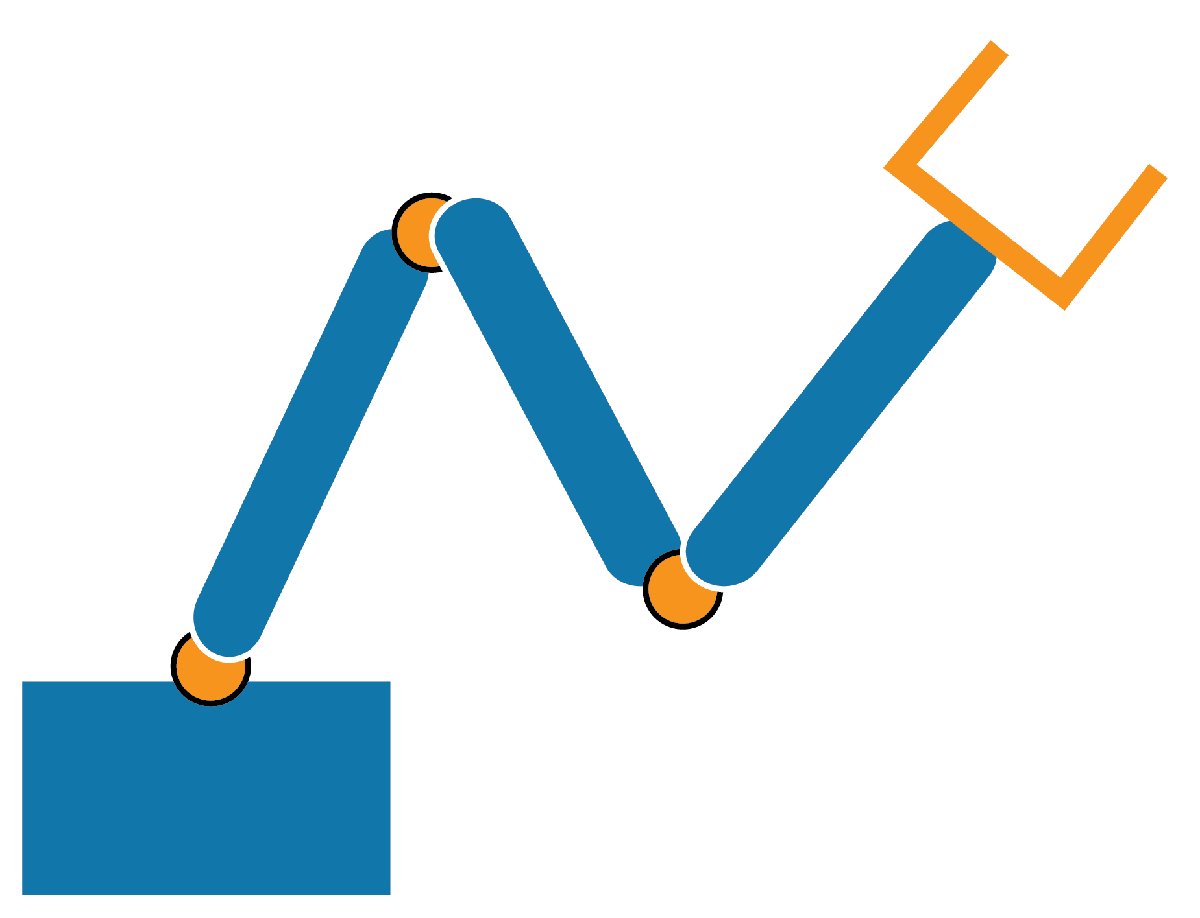

This script will help you visualize the possible configurations of the robot as it attempts to reach different end-effector locations and the impact of the degrees of freedom available on those results.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Define a Configuration Space

We can describe the three-joint arm with 6 numbers: the fixed lengths of each arm component and the variable angles $q_1$, $q_2$ and $q_3$ defining the angles of each joint. For the first example, let's assume that the arm is located in the xy-plane with arm lengths $L_{1}$, $L_2$ and $L_3$ in meters.

 **Exercise 1.** Write down a formula to compute the Cartesian coordinates of the end effector, $(x_E,y_E)$, in terms of $L_1$, $L_2$, $L_3$ and the angles $\theta_1$, $\theta_2$, and $\theta_3$. 

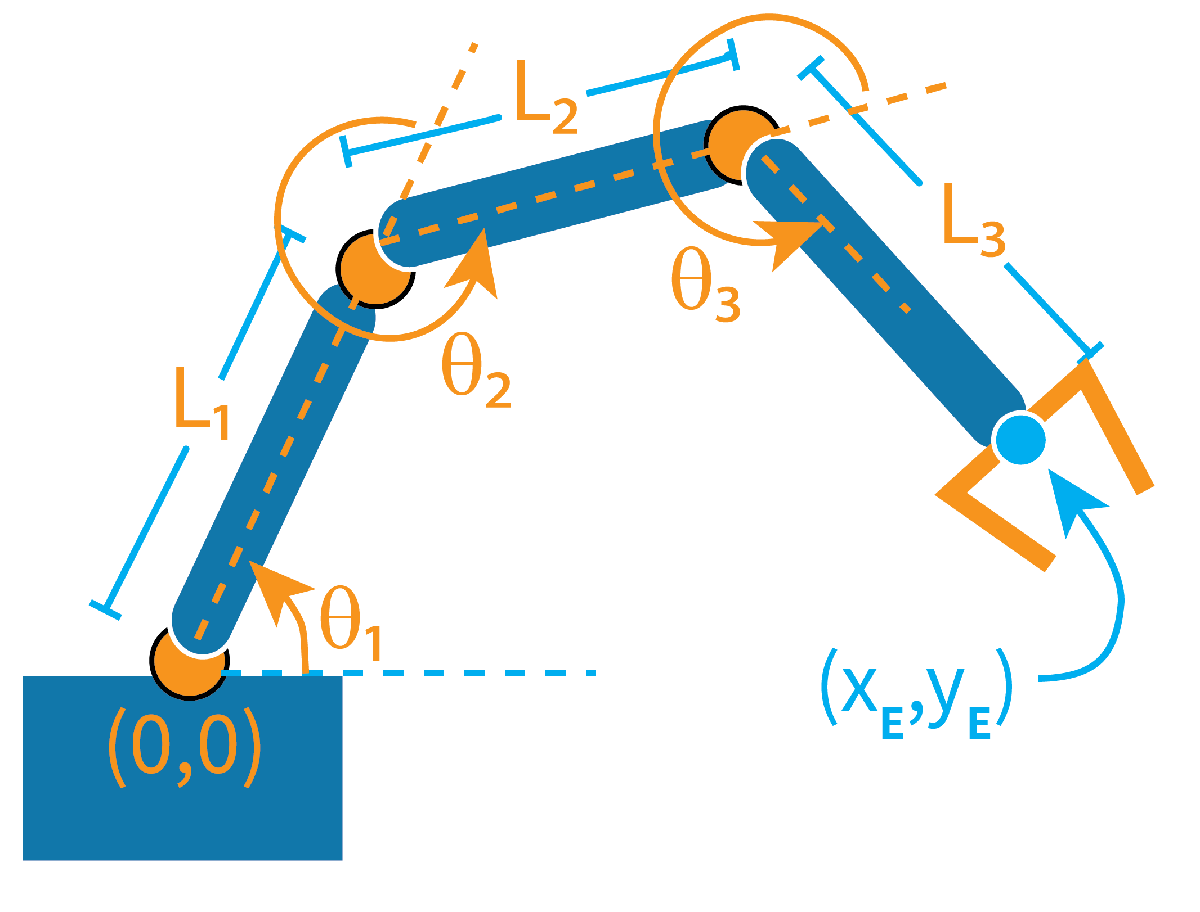

**Solution:**

### **Set up the Parameters of the Arm**

Define specific values for the lengths of each component of the arm:

L_1 = 1;   % m
L_2 = 0.5;  % m
L_3 = 0.25; % m

The angular precision of our controls will also matter. You can control the number of angles available at each joint with the following spinner. Note that a larger number of possible angles means a smaller angular distance to the next possible joint value.

NumberOfPossibleAngles = 35;

Set the range of values, in radians, possible for each joint:

Theta1Vals = DefineAnglePossibilities(-pi,pi,NumberOfPossibleAngles); % radians measured counterclockwise from the +x axis
Theta2Vals = DefineAnglePossibilities(-pi,pi,NumberOfPossibleAngles); % radians measured counterclockwise from the +L_1 axis
Theta3Vals = DefineAnglePossibilities(-pi,pi,NumberOfPossibleAngles); % radians measured counterclockwise from the +L_2 axis

Use `meshgrid` to define all the possible combinations of $\theta$ values. This will allow us to define every possible configuration of the robotic arm and visualize the result.

[Theta1,Theta2,Theta3] = meshgrid(Theta1Vals,Theta2Vals,Theta3Vals);

 **Reflect**. 

- What do you think `meshgrid` does?

- What is the `size` of `Theta1`? 

- What is the `size` of `Theta1(:)`?

### Visualize the Configuration Space

The set of all reachable points is called a configuration space. This example visualizes the configuration space of a two-link robotic arm.

ConfigurationSpaceX = L_1*cos(Theta1(:))+L_2*cos(Theta1(:)+Theta2(:));
ConfigurationSpaceY = L_1*sin(Theta1(:))+L_2*sin(Theta1(:)+Theta2(:));
scatter(ConfigurationSpaceX,ConfigurationSpaceY,".")

Set the $x$- and $y$-axis limits to be the maximum possible reach of this robotic arm with no angular constraints. This will let you compare the results with different angular restrictions more easily. 

TotLength = L_1+L_2;
xlim([-TotLength TotLength])
ylim([-TotLength TotLength])
xlabel("X location (m)")
ylabel("Y location (m)")

Set the axis to be square so that circles appear to be circles and not ellipses.

axis square

Add a title with the known constraints:

title("Configuration space with $L_1=$"+L_1+", and $L_2=$" + L_2,Interpreter="latex")

subtitle(Angles2String(Theta1Vals(1),Theta1Vals(end)," \theta_1 ") + " and " + ...
    Angles2String(Theta2Vals(1),Theta2Vals(end)," \theta_2 "),Interpreter="latex")

 **Exercise 2. **Compute the set of coordinate values that are reachable by the end effector of this 3-link robotic arm given the numerical constraints defined in the previous section and the equation(s) you found in Exercise 1. Modify the code in lines 9-21 as required.

  **Try. **How does your configuration space change if you do the following?

- Choose different values for `L_1`, `L_2`, and `L_3`.

- Choose different values for the angular precision.

 **Reflect**. Given fixed robotic arms of length `L_1`, `L_2`, and `L_3`, does each point in this configuration space correspond to a unique set of angles or is there more than one possibility?

## Counting Possibilities

A robot operates in the physical world, not in an idealized mathematical space. This means that we can decide how close is close enough to say that the robot has reached a fixed point. We can set a tolerance value for this distance. How close, in meters, do we want to be to the precise point we want to reach?

Tolerance = 0.1;

Use a built-in function, [`histcounts2`](https://www.mathworks.com/help/matlab/ref/histcounts2.html), to count the number of points in your configuration space in each 2D grid area defined by your chosen `Tolerance`.

[NumRoutes,Xedges,Yedges] = histcounts2(ConfigurationSpaceX,ConfigurationSpaceY,NumBins=ceil((L_1+L_2+L_3)/(Tolerance/2)));
MaxPaths = max(NumRoutes,[],"all")

Set up a [colormap](https://www.mathworks.com/help/matlab/ref/colormap.html). 

cm = [0 0 0; parula(MaxPaths)];

The local function `DefineColors` maps the values found by `histcounts2` onto each point in the configuration space, as appropriate. 

[MyColors,MyCounts] = DefineColors(NumRoutes,Xedges,Yedges,cm,ConfigurationSpaceX,ConfigurationSpaceY);

Define and label a scatter plot of the configuration space data colored by the number of routes the robot can take to reach each point.

ax = gca;
s=scatter(ax,ConfigurationSpaceX,ConfigurationSpaceY,round(Tolerance*1000),"s","filled",CData=MyColors);
xlim([-(L_1+L_2+L_3) L_1+L_2+L_3])
ylim([-(L_1+L_2+L_3) L_1+L_2+L_3])
axis square
xlabel("X location (m)")
ylabel("Y location (m)")
title("Configuration space")

% Set up the color legend
MyTicks = DefineMyTicks(MaxPaths);
cb = colorbar(Colormap=cm(2:end,:),Ticks=(MyTicks-1)./MaxPaths,TickLabels=string(MyTicks));
ylabel(cb,'Number of Routes','FontSize',12,'Rotation',270)

% Add custom data tips that identify the number of paths to the selected
% point on the plot
NewDataTipRow = dataTipTextRow("Paths",MyCounts);
s.DataTipTemplate.DataTipRows(end) = NewDataTipRow;

Set the color to show for unreachable areas:

ax.Color = [1.000 1.000 1.000];
ax.Parent.Color = ax.Color;
ax.Title.Color = 1-ax.Color;

opts = DefineOptions(MyCounts);

 **Reflect**.

- Why are there unreachable areas?

- Do you see any patterns in the configuration space?

### Identify Specific Paths

ShowExamplePaths = opts(1);
ChoosePoint = randsample(find(MyCounts==double(ShowExamplePaths)),1);

% Print out the chosen point
disp("You have chosen the point (" + ConfigurationSpaceX(ChoosePoint) + ", " + ConfigurationSpaceY(ChoosePoint)+").")

% Identify all the paths available to that point
[xCenter,yCenter,IdxInTol] = FindAllPts(ChoosePoint, Xedges, Yedges,...
    ConfigurationSpaceX,ConfigurationSpaceY,Tolerance);
MyAngles = [Theta1(IdxInTol),Theta1(IdxInTol)+Theta2(IdxInTol),Theta1(IdxInTol)+Theta2(IdxInTol)+Theta3(IdxInTol)];
MyEndPts = [ConfigurationSpaceX(IdxInTol),ConfigurationSpaceY(IdxInTol)];

% Display the paths
figure
for p = 1:nnz(IdxInTol)
    hold on
    Waypoints = [0 0; ...
        L_1*cos(MyAngles(p,1)) L_1*sin(MyAngles(p,1)); ...
        L_1*cos(MyAngles(p,1))+L_2*cos(MyAngles(p,2)) L_1*sin(MyAngles(p,1))+L_2*sin(MyAngles(p,2));...
        MyEndPts(p,1) MyEndPts(p,2)...
        ];
    plot(Waypoints(:,1),Waypoints(:,2),"-",LineWidth=2,SeriesIndex=p+1)
    scatter(Waypoints(:,1),Waypoints(:,2),"*",SeriesIndex=1)
    hold off
end

% Add a diamond marker on the target point and a circle around the area
% within tolerance, if desired
ShowToleranceRegion = true;
if ShowToleranceRegion
    hold on
    scatter(ConfigurationSpaceX(ChoosePoint),ConfigurationSpaceY(ChoosePoint),"diamond","filled",SeriesIndex=p+2,MarkerEdgeColor=[0 0 0])
    viscircles([xCenter yCenter],Tolerance);
    hold off
end

% Uncomment to see visualized in the entire space of solutions
% xlim([-TotLength TotLength])
% ylim([-TotLength TotLength])

axis square
title("Sample Paths with End Effector within Tolerance")
xlabel("Position (m)")
ylabel("Position (m)")

  **Try. **

- When the possible angular values are all from $-\pi$ to $\pi$, the most common result is that all paths overlap perfectly even if there are 8 ways to get to a point. Refine the operating conditions of your robot so that there are clearly distinct paths that reach the same point. What did you need to do?

- Look at points that have different numbers of paths. What patterns do you see? 

- Reduce the range of motion for one or more joints. What does that do to your configuration space?

 **Exercise 3.**  At the beginning of this script, we claimed that the possible positions of a robotic arm are related to the idea of a null space. This three-linkage robotic arm (ignoring the end-effector) has three rotational degrees of freedom (DOF): one for each rotational joint. Let's assume that our robot is mathematically perfect and can move continuously within its rotational constraints. Rather than the limited set of `Theta1Vals` angles, each joint can take *any* angle greater than $-\pi$ and less than or equal to $\pi$.

- If there is only one link of length `L_1`, and one rotational joint at the origin, what is the resulting configuration space? That is, where can the robot reach? How many ways can it get there? This is called 1 DOF.

- If there are two links of length `L_1` and `L_2` and two rotational joints, what is the resulting configuration space? That is, where can the robot reach? How many ways can it get there? This is called 2 DOF.

- If there are three links of lengths `L_1`, `L_2`,and `L_3` and three rotational joints, what is the resulting configuration space? That is, where can the robot reach? How many ways can it get there? This is called 3 DOF.

**Solution:**

 **Reflect**.

- What are the advantages and disadvantages of adding additional degrees of freedom to a robotic arm?

- What is the dimension null space of a 3 DOF robot in two dimensions? What about of a 2 DOF robot in two dimensions?

## Further Exploration

There is an entire curriculum module on robotic motion. It does assume that you have studied calculus, as well as linear algebra. Although you will not need to solve any calculus problems to work through the module, it will help if you are familiar with the notation and terminology.

[Robotic Manipulators](https://github.com/MathWorks-Teaching-Resources/Robotic-Manipulators) is available on [GitHub](https://github.com/MathWorks-Teaching-Resources/Robotic-Manipulators) or [](https://www.mathworks.com/matlabcentral/fileexchange/130124-robotic-manipulators) or [](https://matlab.mathworks.com/open/github/v1?repo=MathWorks-Teaching-Resources/Robotic-Manipulators&project=Robotic-Manipulators.prj)

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

function [MyColors,MyCounts] = DefineColors(NumRoutes,Xedges,Yedges,cm,X,Y)
if min(X,[],"all")<Xedges(1) || max(X,[],"all")>Xedges(end)
    error("X is outside the range of allowable values.")
end
if min(Y,[],"all")<Yedges(1) || max(Y,[],"all")>Yedges(end)
    error("Y is outside the range of allowable values.")
end
MyCounts = arrayfun(@(x,y)DefCounts(x,y,Xedges,Yedges,NumRoutes),X,Y);
MyColorsRed = arrayfun(@(ColNum)DefColor(ColNum,cm,1),MyCounts,UniformOutput=true);
MyColorsGreen = arrayfun(@(ColNum)DefColor(ColNum,cm,2),MyCounts,UniformOutput=true);
MyColorsBlue = arrayfun(@(ColNum)DefColor(ColNum,cm,3),MyCounts,UniformOutput=true);
MyColors = [MyColorsRed MyColorsGreen MyColorsBlue];
end

Return to text

function ColorNumber = DefCounts(xVal,yVal,Xedges,Yedges,NumRoutes)
[xIdx, yIdx] = FindRouteBin(xVal, Xedges, yVal, Yedges);
ColorNumber = NumRoutes(xIdx,yIdx);
end

function OneColor = DefColor(ColorNumber,cm,cIdx)
OneColor = cm(ColorNumber+1,cIdx);
end

function [xMiddle,yMiddle,InTolerance] = FindAllPts(ChoosePt,Xedges,Yedges,AllX,AllY,Tolerance)
[xIdx, yIdx] = FindRouteBin(AllX(ChoosePt), Xedges, AllY(ChoosePt), Yedges);
xMiddle = (Xedges(xIdx)+Xedges(xIdx+1))/2;
yMiddle = (Yedges(yIdx)+Yedges(yIdx+1))/2;
InTolerance = ((AllX-xMiddle).^2+(AllY-yMiddle).^2)<Tolerance^2;
% Theta1Vals = Theta1(InTolerance);
% Theta2Vals = Theta2(InTolerance);
% Theta3Vals = Theta3(InTolerance);
end

function [xIdx, yIdx] = FindRouteBin(xVal, Xedges, yVal, Yedges)
xIdx = find(xVal<Xedges,1)-1;
yIdx = find(yVal<Yedges,1)-1;
end

function outStr = Angles2String(langle,rangle,inStr)
    [lstr,flag] = Angle2String(langle);
    if flag
        outStr = lstr+ " $< " + inStr + " \leq$ ";
    else
        outStr = lstr+ " $\leq " + inStr + " \leq$ ";
    end
    rstr = Angle2String(rangle);
    outStr = outStr + rstr;
end

function [str,flag] = Angle2String(angle)
options = [pi pi/2 0];
flag = 0;
test = abs(options-abs(angle))<1e-10;
if nnz(test) == 0
    if angle+pi < 0.63
        test(1) = 1;
        flag=1;
    else
        error("Unexpected angle.")
    end
end
StringOptions = ["\pi" "\frac{\pi}{2}" "0"];
str = StringOptions(test);
if sign(angle) == -1
    str = "-"+str;
end
str = " $"+str+"$ ";
end

function opts = DefineOptions(MyCounts)
if length(unique(MyCounts))>5
    PathOpts = unique(MyCounts);
    RandChoices = randsample(PathOpts,5);
    opts = string(unique([min(PathOpts); max(PathOpts);RandChoices]));
else
    opts = string(unique(MyCounts));
end
end

function AngPoss = DefineAnglePossibilities(LeftAngLim,RightAngLim,AngularResolution)
AngPoss = linspace(LeftAngLim,RightAngLim,AngularResolution);
if cos(LeftAngLim) == -1 && cos(RightAngLim) == -1
    AngPoss = AngPoss(2:end);
end
end

function MyTicks = DefineMyTicks(MaxPaths)
if MaxPaths > 10
    MyTicks = 1:ceil(MaxPaths/10):MaxPaths;
    if MyTicks(end) ~= MaxPaths
        if MyTicks(end)/MaxPaths < 0.93
            MyTicks = [MyTicks MaxPaths];
        else
            MyTicks(end) = MaxPaths;
        end
    end
else
    MyTicks = 1:MaxPaths;
end
end